cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis')
load South.mat  % loads in matlab file
s = south; clear south
cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis\Data')
load Met.mat
run('GeneralSettings.m')

dn = s.dn; 
depth = s.Depth1_m; 
temp = s.Temp1_C; 
sal = s.Salinity1_psu; 
DO_mgL = s.DO1_Conc_mgL; 
pH = s.pH; 

ind = find(dn >= datenum(2021,10,23,00,00,00) & dn < datenum(2021,10,27,00,00,00));

south.dn = dn(ind);
south.depth = depth(ind);
south.temp = temp(ind);
south.sal = sal(ind);
south.DO_mgL = DO_mgL(ind);
south.pH = pH(ind);
clear s dn depth sal DO_mgL pH temp ind

% Finds indices for AM and PM 
AM = find(AMtime == 1);
PM = find(PMtime == 1);

% Convert to mol/m3 and calculated saturation for different temp/salinity 
south.rho = gsw_sigma0(south.sal,south.temp)+1000; % Density in kg/m3

% mg/L to umol/L
south.DO_umolL = south.DO_mgL * 1000 / 31.9988;
% umol/L to umol/kg
south.DO_umolkg = south.DO_umolL./south.rho*1000; 
south.DO_molm3 = south.rho.*south.DO_umolkg./1e6;
south.waterDOsat_molm3 = gasmoleq(south.sal,south.temp,'O2'); % At saturation for DO in mol/m3
south.DO_per = south.DO_molm3./south.waterDOsat_molm3*100;


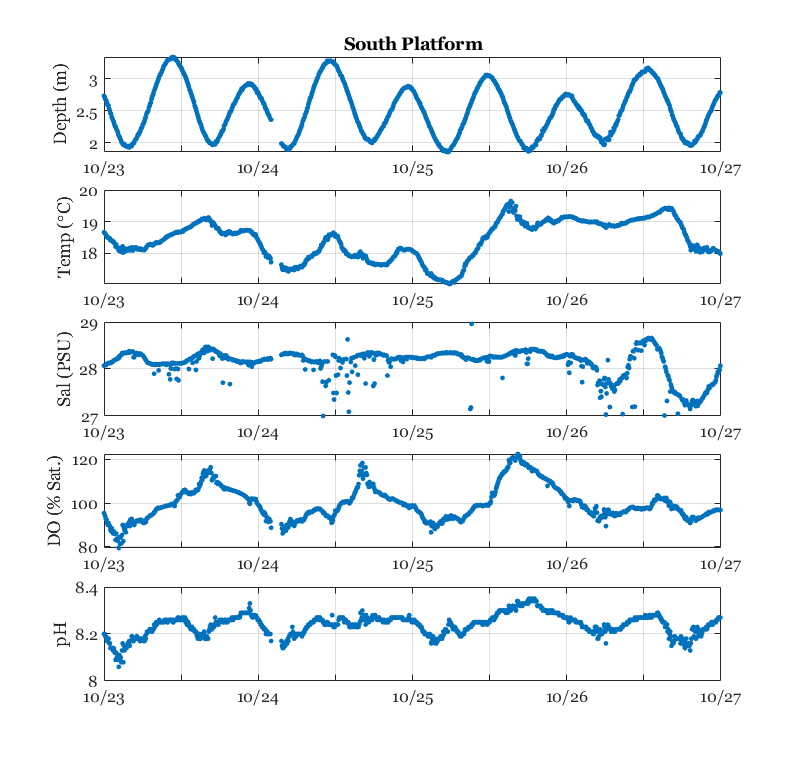

f = figure;
f.Position = [0 0 1040 1000]; 

ax1 = subplot(5,1,1); % Breaks figure into plots (3 rows, 1 column, 1st plot)
plot(south.dn,south.depth,'o','MarkerSize',3,'MarkerFaceColor',blue)
ylabel('Depth (m)','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
% datetick('x','mm/dd','keeplimits')
grid on
% set(ax1,'Color',[0.182 0.215 0.168])
set(ax1,'Color','none')
set(ax1,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});
title('South Platform','FontSize',16)

ax2 = subplot(5,1,2); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.temp,'o','MarkerSize',3,'MarkerFaceColor',blue)
ylabel('Temp (\circC)','FontName','Georgia')   
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
% set(ax2,'Color',[0.182 0.215 0.168])
set(ax2,'Color','none')
set(ax2,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax3 = subplot(5,1,3); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.sal,'o','MarkerSize',3,'MarkerFaceColor',blue) 
ylabel('Sal (PSU)','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
ylim([27 29])
grid on
% set(ax3,'Color',[0.182 0.215 0.168])
set(ax3,'Color','none')
set(ax3,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax4 = subplot(5,1,4); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.DO_per,'o','MarkerSize',3,'MarkerFaceColor',blue)
ylabel('DO (% Sat.)','FontName','Georgia') %change to percent
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
% set(ax4,'Color',[0.182 0.215 0.168])
set(ax4,'Color','none')
set(ax4,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax5 = subplot(5,1,5); % Breaks figure into plots (3 rows, 1 column, 2nd plot)
plot(south.dn,south.pH,'o','MarkerSize',3,'MarkerFaceColor',blue) 
ylabel('pH','FontName','Georgia') 
xlim([datenum(2021,10,23,00,00,00) datenum(2021,10,27,00,00,00)])
grid on
% set(ax5,'Color',[0.182 0.215 0.168])
set(ax5,'Color','none')
set(ax5,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

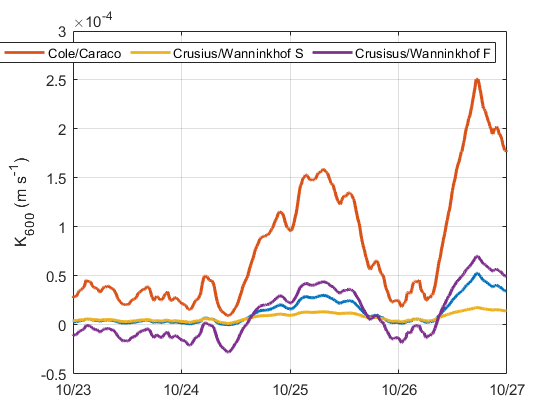

% For wind measurements (U10) and water measurements (Cw)
nm = 30; % number of points for moving mean

met.windspeed_ms = met.WindSpeed_mph*1609.34/3600; % mph --> m/s
%Windspeed to time of platform measurements 
south.windspeed_ms = interp1(met.dn,met.windspeed_ms,south.dn);
U10 = movmean(south.windspeed_ms,nm); % m/s  
sal = movmean(south.sal,nm); 
temp = movmean(south.temp,nm);

% Calculate Scmidt number for platform
[D_DO, Sc_DO] = gasmoldiff(sal,temp,'O2');

% Air-sea parameterizations (cm/hr) and converted to m/s
k1 = (0.24*(U10.^2))/100/3600; % Wanninkhof (2014)
k2 = (2.07 + 2.15*(U10.^1.7))/100/3600; % Cole and Caraco (1998)
k3 = (0.72*U10)/100/3600; % Crusius and Wanninkhof (2014) U < 3.7 m/s
k4 = (-13.3 + 4.33*U10)/100/3600; % Crusius and Wanninkhof (2014) U > 3.7 m/s

figure
plot(south.dn,k1,'LineWidth',2)
hold on
plot(south.dn,k2,'LineWidth',2)
plot(south.dn,k3,'LineWidth',2)
plot(south.dn,k4,'LineWidth',2)
ylabel('K_6_0_0 (m s^-^1)')
datetick
grid on
legend('Wanninkhof','Cole/Caraco','Crusius/Wanninkhof S','Crusisus/Wanninkhof F',...
    'Location','north','Orientation','Horizontal')

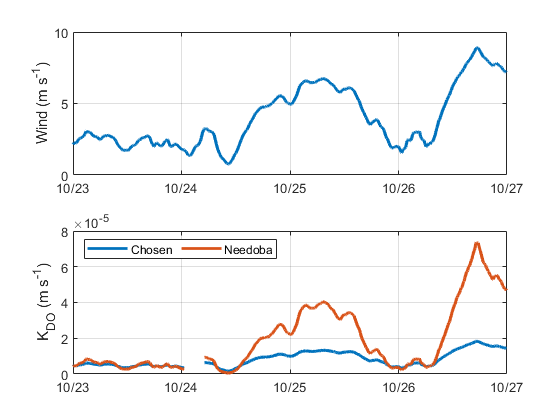


% Convert from CO2 referenced equation (k600) to O2 with Schmidt number ratio
k_picked = k3; % Chosen parameterization
k = (Sc_DO/600).^-0.5 .*k_picked; % units same as wind speed 
k6 = (0.31*(U10.^2).*((Sc_DO/660).^-0.5))/100/3600; % Needoba Chapter m/s

figure
subplot(2,1,1)
plot(south.dn,U10,'Linewidth',2)
ylabel('Wind (m s^-^1)')
datetick
grid on

subplot(2,1,2)
plot(south.dn,k,'Linewidth',2)
hold on
plot(south.dn,k6,'Linewidth',2)
ylabel('K_D_O (m s^-^1)')
datetick
grid on
legend('Chosen','Needoba','Location','NW','Orientation','Horizontal')

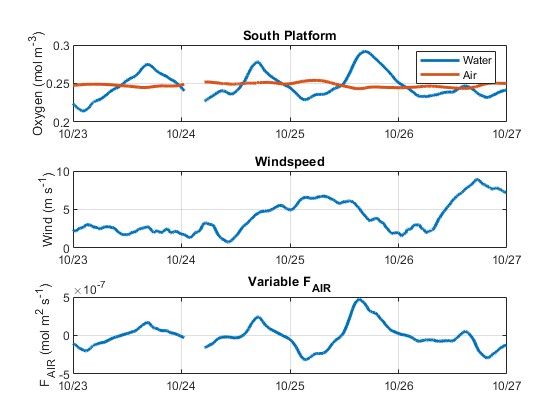

% Calculate air sea gas exchange 

Ca = gasmoleq(sal,temp,'O2'); % mol/m3
Cw = movmean(south.DO_molm3,nm); % mol/m3      % *** nm is assigned with windspeed smoothing above 
Fair0 = k.*(Cw - Ca); %

figure
subplot(3,1,1)
plot(south.dn,Cw,'Linewidth',2)
hold on
plot(south.dn,Ca,'Linewidth',2)
ylabel('Oxygen (mol m^-^3)')
legend('Water','Air')
datetick
grid on
title('South Platform')

subplot(3,1,2)
plot(south.dn,U10,'Linewidth',2)
ylabel('Wind (m s^-^1)')
datetick
grid on
title('Windspeed')

subplot(3,1,3)
plot(south.dn,Fair0,'Linewidth',2)
ylabel('F_A_I_R (mol m^2 s^-^1)')
datetick
grid on
title('Variable F_A_I_R')

%Convert to mmol/m2/hr 
Fair = Fair0(2:end)*3600*1000; % remove first point to match flux timeseries (calc from diff) 
depth = south.depth(2:end);
% Calculate delDO/dt from oxygen time series
% convert mol/m3 (every 6 min) to mmol/m2/hr (water depth = variable m)
delDOdt0 = (diff(Cw)/(1/10)).*depth*1000; % reading every 6 min 

% Make adjustment for Air-Sea gas exchange. 
% Convert Fair from mol/m2/s to mmol/m2/hr to match delDOdt0
delDOdt = delDOdt0 + Fair; % Oposite of constant flux calc below
dn = south.dn(2:end); % remove first point to match flux timeseries (calc from diff) 

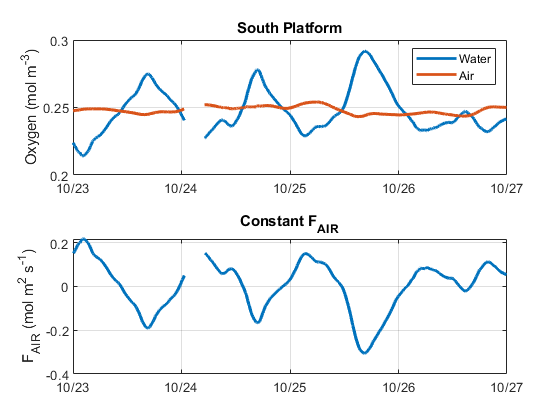


% Calculate constant air-sea gas exchange
% From Needoba Chapter 
% *** Why is this opposite sign of above calcualtion 
DOmeasper = Cw./Ca*100; 
DOdir = NaN(1,length(dn));
for i = 1:length(dn)
    DOdir(i) = 1 - ((DOmeasper(i) + DOmeasper(i+1))/200);
end

constant = 0.5/31.9988*1000; % g O2/m2/hr to mol 02/m2/hr % From Needoba Chapter 
Fair_constant = DOdir'*constant/10;
delDOdtk = delDOdt0 - Fair_constant; 

figure
subplot(2,1,1)
plot(south.dn,Cw,'Linewidth',2)
hold on
plot(south.dn,Ca,'Linewidth',2)
ylabel('Oxygen (mol m^-^3)')
legend('Water','Air')
datetick
grid on
title('South Platform')

subplot(2,1,2)
plot(dn,Fair_constant,'Linewidth',2)
ylabel('F_A_I_R (mol m^2 s^-^1)')
datetick
grid on
title('Constant F_A_I_R')

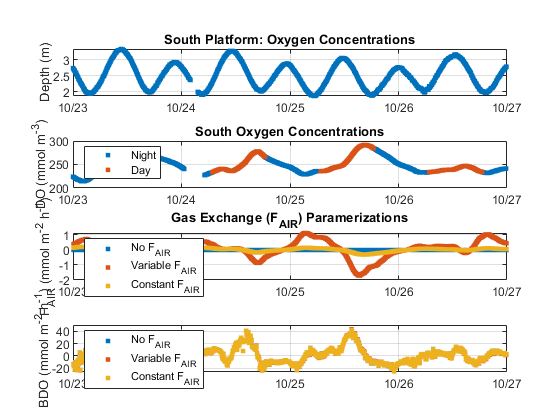


figure 
subplot(4,1,1)
plot(south.dn,south.depth,'.','MarkerSize',10) % convert to mmol/m3
datetick
grid on
ylabel('Depth (m)')
title('South Platform: Oxygen Concentrations')

subplot(4,1,2)
plot(south.dn(PM),Cw(PM)*1000,'.','MarkerSize',10) % convert to mmol/m3
hold on
plot(south.dn(AM),Cw(AM)*1000,'.','MarkerSize',10)
datetick
grid on
ylabel('DO (mmol m^-^3)')
title('South Oxygen Concentrations')
legend('Night','Day','Location','NW')

subplot(4,1,3)
plot(dn,zeros(1,length(dn)),'.','MarkerSize',10)
hold on
plot(dn,-Fair,'.','MarkerSize',10)
plot(dn,Fair_constant,'.','MarkerSize',10)
datetick
grid on
legend('No F_A_I_R','Variable F_A_I_R','Constant F_A_I_R','Location','SW')
ylabel('F_A_I_R (mmol m^-^2 h^-^1)')
title('Gas Exchange (F_A_I_R) Paramerizations')

subplot(4,1,4)
plot(dn,delDOdt0,'.','MarkerSize',10)
hold on
plot(dn,delDOdt,'.','MarkerSize',10)
plot(dn,delDOdtk,'.','MarkerSize',10)
datetick
grid on
ylabel('BDO (mmol m^-^2 h^-^1)')
legend('No F_A_I_R','Variable F_A_I_R','Constant F_A_I_R','Location','SW')

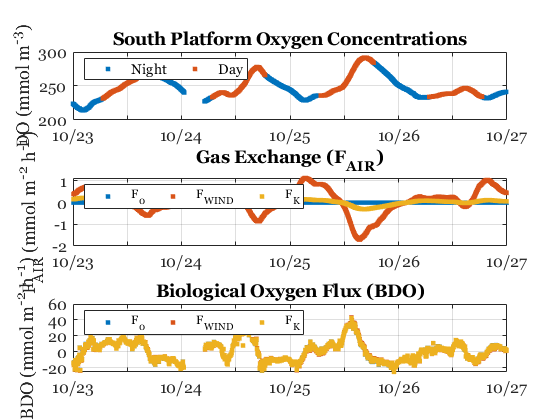


figure 
ax1 = subplot(3,1,1);
plot(south.dn(PM),Cw(PM)*1000,'.','MarkerSize',10) % convert to mmol/m3
hold on
plot(south.dn(AM),Cw(AM)*1000,'.','MarkerSize',10)
datetick
grid on
ylabel('DO (mmol m^-^3)')
set(ax1,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});
title('South Platform Oxygen Concentrations','FontName','Georgia','FontSize',14)
legend('Night','Day','Location','NW','Orientation','Horizontal')

ax2 = subplot(3,1,2);
plot(dn,zeros(1,length(dn)),'.','MarkerSize',10)
hold on
plot(dn,-Fair,'.','MarkerSize',10)
plot(dn,Fair_constant,'.','MarkerSize',10)
datetick
grid on
ylabel('F_A_I_R (mmol m^-^2 h^-^1)','FontName','Georgia','FontSize',12)
set(ax2,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});
legend('F_0','F_W_I_N_D','F_K','FontName','Georgia','Location','NW','FontSize',9,'Orientation','Horizontal')

title('Gas Exchange (F_A_I_R)','FontName','Georgia','FontSize',14)


ax3 = subplot(3,1,3);
plot(dn,delDOdt0,'.','MarkerSize',10)
hold on
plot(dn,delDOdt,'.','MarkerSize',10)
plot(dn,delDOdtk,'.','MarkerSize',10)
datetick
ylim([-25 60])
grid on
title('Biological Oxygen Flux (BDO)','FontName','Georgia','FontSize',14)
ylabel('BDO (mmol m^-^2 h^-^1)','FontName','Georgia','FontSize',12)
set(ax3,'FontName','Georgia','FontSize',12,'XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});
legend('F_0','F_W_I_N_D','F_K','FontName','Georgia','Location','NW','FontSize',9,'Orientation','Horizontal')

PM1 = 1:65; % Indices for time periods 
PM2 = 185:307;
PM3 = 426:547;
PM4 = 666:787;
PM5 = 906:958;

AM1 = 66:184;
AM2 = 308:425;
AM3 = 548:665;
AM4 = 788:905;

% With Variable Fair 
NEP1 = sum(delDOdt(AM1))/10 

NEP1 = 105.5460

NR2 = sum(delDOdt(PM2))/10 %mmol/m2/hr % changed to 10 because 10 readings in an hour 

NR2 = NaN

NEP2 = sum(delDOdt(AM2))/10 

NEP2 = 94.4677

NR3 = sum(delDOdt(PM3))/10 %mmol/m2/hr 

NR3 = -85.0961

NEP3 = sum(delDOdt(AM3))/10 %mmol/m2/hr 

NEP3 = 143.3876

NR4 = sum(delDOdt(PM4))/10 %mmol/m2/hr 

NR4 = -120.0128

NEP4 = sum(delDOdt(AM4))/10 %mmol/m2/hr 

NEP4 = 5.7577


NEM1 = NEP1 + NR2

NEM1 = NaN

NEM2 = NEP2 + NR3

NEM2 = 9.3716

NEM3 = NEP3 + NR4

NEM3 = 23.3747


meanR2 = nanmean(delDOdt(PM2))

meanR2 = -7.6162

meanR3 = nanmean(delDOdt(PM3))

meanR3 = -6.9751

meanR4 = nanmean(delDOdt(PM4))

meanR4 = -9.8371


DRR2 = meanR2*24

DRR2 = -182.7889

DRR3 = meanR3*24

DRR3 = -167.4021

DRR4 = meanR4*24

DRR4 = -236.0908


GPP1 = NEP1 + length(AM1)/10*abs(meanR2)

GPP1 = 196.1788

GPP2 = NEP2 + length(AM2)/10*abs(meanR3)

GPP2 = 176.7737

GPP3 = NEP3 + length(AM3)/10*abs(meanR4)

GPP3 = 259.4655

GPP4 = NEP4 + length(AM4)/10*abs(meanR4) % *** uses R4

GPP4 = 121.8357

% For Fconstant

NR1 = sum(delDOdtk(PM1))/10 %mmol/m2/hr 

NR1 = 9.7746

NEP1 = sum(delDOdtk(AM2))/10 

NEP1 = 92.7075

NR2 = sum(delDOdtk(PM2))/10 %mmol/m2/hr 

NR2 = NaN

NEP2 = sum(delDOdtk(AM3))/10 

NEP2 = 138.7249

NR3 = sum(delDOdtk(PM3))/10 %mmol/m2/hr 

NR3 = -80.9305


NEM1 = NEP1 + NR2

NEM1 = NaN

NEM2 = NEP2 + NR3

NEM2 = 57.7944


meanR1 = nanmean(delDOdtk(PM1))

meanR1 = 1.5038

meanR2 = nanmean(delDOdtk(PM2))

meanR2 = -7.6075

meanR3 = nanmean(delDOdtk(PM3))

meanR3 = -6.6336


DRR1 = meanR1*24

DRR1 = 36.0909

DRR2 = meanR2*24

DRR2 = -182.5809

DRR3 = meanR3*24

DRR3 = -159.2075


GPP1 = NEP1 + length(AM2)/10*abs(meanR2)

GPP1 = 182.4764

GPP2 = NEP2 + length(AM3)/10*abs(meanR3)

GPP2 = 217.0019

% For Fair = 0  

NR1 = sum(delDOdt0(PM1))/10 %mmol/m2/hr 

NR1 = 10.8842

NEP1 = sum(delDOdt0(AM2))/10 

NEP1 = 92.6170

NR2 = sum(delDOdt0(PM2))/10 %mmol/m2/hr 

NR2 = NaN

NEP2 = sum(delDOdt0(AM3))/10 

NEP2 = 137.5682

NR3 = sum(delDOdt0(PM3))/10 %mmol/m2/hr 

NR3 = -80.3020


NEM1 = NEP1 + NR2

NEM1 = NaN

NEM2 = NEP2 + NR3

NEM2 = 57.2662


meanR1 = nanmean(delDOdt0(PM1))

meanR1 = 1.6745

meanR2 = nanmean(delDOdt0(PM2))

meanR2 = -7.6218

meanR3 = nanmean(delDOdt0(PM3))

meanR3 = -6.5821


DRR1 = meanR1*24

DRR1 = 40.1879

DRR2 = meanR2*24

DRR2 = -182.9229

DRR3 = meanR3*24

DRR3 = -157.9711


GPP1 = NEP1 + length(AM2)/10*abs(meanR2)

GPP1 = 182.5541

GPP2 = NEP2 + length(AM3)/10*abs(meanR3)

GPP2 = 215.2373